X点でのpsi_commonや電流密度、電場を時系列で求めるコード

plot開始点は合体率が0を超える時間から

（コード重いので3こずつくらいで出力した方が安心）

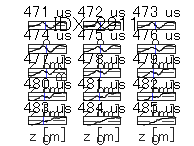

clearvars
% yourname = 'C:\Users\Moe Akimitsu\';
% f = fullfile(yourname,'Documents','GitHub','test-open');
% addpath(genpath(f));
% %addpath(fullfile(yourname,'Documents','GitHub','test-open','pcb'));
% f = fullfile(yourname,'Documents','GitHub','SXR_test');
% addpath(f);
%%%適宜変更
%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath
pathname.save=getenv('save_path'); %保存先

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得
%  node='Crowbar_us_';  % 検索する列の名前. T.Properties.VariableNamesで一覧表示できる
%  pat=454;   % 検索パターン（数値なら一致検索、文字なら含む検索）　
% 
% subT=searchlog(T,node,pat);% ログのテーブルから当てはまるものを抽出した新しいテーブルを作成

%prompt = 'number: '
%shotlist=[3394,];
%subT=T(shotlist,:);
%IDXlist=shotlist(isfinite(subT.d_tacq));
%IDX=T.number
%IDX=input(prompt)

IDXlist=[2911:2913 2925 2926 2927 2931 2933 2947:2950 2942 2943 2946];
%IDXlist=2911 %[2911 2927 2933 2948 2943]
%(a)211223/IDX2870:2920(42:44)/2911:2913/dtacq3592:3594
%(b)211224/IDX2922:2950(4,5,8)/2925,2926,2927/dtacq3606,3607,3609
%(c)211224/IDX2922:2950(10,12)/2931,2933/dtacq3611,3613
%(d)211224/IDX2922:2950(26:29)/2947:2950/dtacq3626-3629
%(e)211224/IDX2922:2950(21,22,25)/2942,2943,2946/dtacq3621,3622,3625

start=470;
frame=15;
for i=1 %numel(IDXlist)
IDX=IDXlist(i);
flow(T, IDX, pathname,start,frame);
end

%mesh値変える！！


function rgwdata = importfile(filename, dataLines)
%IMPORTFILE テキスト ファイルからデータをインポート
%  UNTITLED = IMPORTFILE(FILENAME) は既定の選択に関してテキスト ファイル FILENAME
%  からデータを読み取ります。  データを table として返します。
%
%  UNTITLED = IMPORTFILE(FILE, DATALINES) はテキスト ファイル FILENAME
%  の指定された行区間のデータを読み取ります。DATALINES
%  を正の整数スカラーとして指定するか、行区間が不連続の場合は正の整数スカラーからなる N 行 2 列の配列として指定します。
%
%  例:
%  Untitled = importfile("X:\results\ts-3u\211222\211222006.rgw", [1, Inf]);
%
%  READTABLE も参照してください。
%
% MATLAB からの自動生成日: 2022/01/15 13:57:51

%% 入力の取り扱い

% dataLines が指定されていない場合、既定値を定義します
if nargin < 2
    dataLines = [1, Inf];
end

%% インポート オプションの設定およびデータのインポート
opts = delimitedTextImportOptions("NumVariables", 18);

% 範囲と区切り記号の指定
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% 列名と型の指定
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "ch6", "ch7", "ch8", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"];
opts.SelectedVariableNames = ["ch6", "ch7", "ch8"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 変数プロパティを指定
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"], "EmptyFieldRule", "auto");

% データのインポート
rgwdata = readtable(filename, opts);

end

function flow(T, IDX, pathname,start,frame)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
offset_TF=isfinite(TF_shot);
Cr=T.Crowbar_us_(IDX);
if isnan(Cr)
    Cr=num2str('-');
end
CB=T.CB1_kV_(IDX);
%start=T.Period_StartTime_(IDX);
if isnan(T.EF_A_(IDX))
    i_EF=150;
else  
    i_EF=T.EF_A_(IDX);
end
% %rgwデータの読み込み->coil current plot用
% filepath.rgw=strcat(pathname.ts3u, '/', string(date),'/' ...
%     ,string(date),num2str(shot,'%03i'),'.rgw');
% 
% if exist(filepath.rgw)~=0
% rgwdata = importfile(filepath.rgw);
% rgwdata.ch6=rgwdata.ch6*(65.7146)*12;
% rgwdata.ch7=rgwdata.ch7*(-57.6030)*3;
% rgwdata.ch8=rgwdata.ch8*(-187.170)*3-50;
% %各ショットのTF,PF1,PF2のcoil current
% plot(repmat([0:0.1:0.1*10000],3,1)',rgwdata{2:end,:})
% legend('TF','PF1','PF2')
% ylabel('coil current [kA]')
% ylim([-250 150])
% xlim([300 550])
% title(strcat('IDX',num2str(IDX),': Cr',num2str(T.Crowbar_us_(IDX))))
% hold off
% end

[B_z,r_probe,z_probe,ch_dist,data,data_raw,shot_num]= get_B_z(date,TF_shot,shot,offset_TF,i_EF,pathname.ts3u);
B_z = B_z([2,3,4,6,7,8],2:end,:);
data = data([2,3,4,6,7,8],2:end,:);
z_probe = z_probe(2:end);
ch_dist = ch_dist([2,3,4,6,7,8],2:end);
r_probe = r_probe([2,3,4,6,7,8]);

mesh_z=50;
mesh_r=50;

z_space = linspace(z_probe(1),z_probe(end),mesh_z);
r_space = linspace(r_probe(1),r_probe(end),mesh_r);
[psi_mesh_z,psi_mesh_r] = meshgrid(z_space,r_space);

psi_store = zeros(length(r_space),length(z_space),frame);
Jt_store = psi_store;
Et_store = psi_store;
Br_store = psi_store;
Bz_store = psi_store;
Vz_store = psi_store;
Vr_store = psi_store;
for i=1:frame
    psi  = get_psi(B_z,r_probe,i+start);
    psi_store(:,:,i)= griddata(z_probe,r_probe,psi,psi_mesh_z,psi_mesh_r,'cubic');
    [j_t,z_space_jt,r_space_jt] = jt(B_z,z_probe,r_probe,i+start);
    Jt_store(:,:,i) = griddata(z_space_jt,r_space_jt,j_t,psi_mesh_z,psi_mesh_r,'v4');
    E_t = Et(B_z,r_probe,i+start);
    Et_store(:,:,i) = griddata(z_probe,r_probe,E_t,psi_mesh_z,psi_mesh_r,'v4');
    Bz_store(:,:,i) = griddata(z_probe,r_probe,B_z(:,:,i+start),psi_mesh_z,psi_mesh_r,'v4');
    Br_store(:,:,i) = Br(psi_store(:,:,i),z_space,r_space);
    Vz_store(:,:,i)=Et_store(:,:,i)./Br_store(:,:,i);
    Vr_store(:,:,i)=-Et_store(:,:,i)./Bz_store(:,:,i);
    vzind1=isoutlier(Vz_store(:,:,i),'median',1);
    vzind2=isoutlier(Vz_store(:,:,i),'median',2);
    vzind3=isoutlier(Vz_store(:,:,i),'median',3);
    Vz_store(vzind1)=NaN;
    Vz_store(vzind2)=NaN;
    Vz_store(vzind3)=NaN;
    vrind1=isoutlier(Vr_store(:,:,i),'median',1);
    vrind2=isoutlier(Vr_store(:,:,i),'median',2);
    vrind3=isoutlier(Vr_store(:,:,i),'median',3);
    Vr_store(vrind1)=NaN;
    Vr_store(vrind2)=NaN;
    Vr_store(vrind3)=NaN;
    clear vzind1 vrind1 vzind2 vrind2 vzind3 vrind3
    Vz_store(abs(Vz_store) > 10*1e+4) = NaN;
    Vr_store(abs(Vr_store) > 10*1e+4) = NaN;
end

[max_psi,max_psi_r]=max(psi_store,[],1); %各時間、各列(z)ごとのpsiの最大値
max_psi=squeeze(max_psi);
psi_xr=zeros(1,frame);
psi_xz=psi_xr;
xr_ind=ones(1,frame).*ceil(mesh_r/2);

% psi_pr=zeros(3,frame);
% xJt=zeros(1,frame);
% xEt=xJt;
% %plot(max_psi)
for i=1:frame
    r_ind=max_psi_r(:,:,i);
    max_psi_ind=find(islocalmax(smooth(max_psi(:,i)),'MaxNumExtrema', 2));
%     if numel(max_psi(min(max_psi_ind),i))==0
%     psi_pr(1,i)=NaN;
%     else
%     psi_pr(1,i)=max_psi(min(max_psi_ind),i);
%     end
%     if numel(max_psi(max(max_psi_ind),i))==0
%     psi_pr(2,i)=NaN;
%     else
%     psi_pr(2,i)=max_psi(max(max_psi_ind),i);
%     end
    if numel(find(islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1)))==0
%         xr_ind(1,i)=NaN;
        psi_xz(1,i)=NaN;
        xJt(1,i)=NaN;
        xEt(1,i)=NaN;
    else
        min_psi_ind=islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1);
        xr=r_ind(min_psi_ind);
        if xr==1 || xr==mesh_r %r両端の場合は検知しない
%             xr_ind(1,i)=NaN;
            psi_xz(1,i)=NaN; 
            xJt(1,i)=NaN;
            xEt(1,i)=NaN;
        else
            psi_xr(1,i)=r_space(xr);
            xr_ind(1,i)=xr;
            psi_xz(1,i)=z_space(min_psi_ind);
            xJt(1,i)=Jt_store(xr,min_psi_ind,i);
            xEt(1,i)=Et_store(xr,min_psi_ind,i);
        end
    end
%     if max_psi(1,i)==max(max_psi(1:end/2,i))
%         psi_pr(1,i)=NaN; %max_psi(1,i);
%     end    
%     if max_psi(end,i)==max(max_psi(end/2:end,i))
%         psi_pr(2,i)=NaN; %max_psi(end,i);
%     end
end
% fitrate=psi_pr(3,:)./min(psi_pr(1:2,:),[],1);
% merge_ind=find(fitrate>=0,1); %fitrateが初めて0以上となる点のindex
% 
% time=[1:frame]+start;

% Vz_edge1=zeros(frame,1);
% Vz_edge2=zeros(frame,1);
% Vz_left=zeros(frame,1);
% Vz_right=zeros(frame,1);
% sheetl=zeros(frame,1);
% sheetr=zeros(frame,1);
% 
% [edge1,~]=islocalmax(Br_store(r_xind,:,i));
% [edge2,~]=islocalmin(Br_store(r_xind,:,i));

column = 5; 
row = ceil(frame/column);
%Brの分布を各時刻でplot
figure
for i=1:frame
subplot(column,row,i)
plot(z_space,Br_store(xr_ind(1,i),:,i),'k-')
xline(psi_xz(1,i),'b-')
% xline(grid2D.zq(1,edge1),'r--')
% xline(grid2D.zq(1,edge2),'r--')
% xline(grid2D.zq(1,lind),'r-')
% xline(grid2D.zq(1,rind),'r-')
yline(0,'k-.')
% xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
xlabel('z [m]')
ylabel('Br')
title(string(i+start-1)+' us')
end
sgtitle(strcat('IDX=',num2str(IDX)))

% %Vz, Vrのplot
% figure('Position', [0 0 1500 1500],'visible','on');
% column = ceil(sqrt(frame)); 
% row = ceil(frame/column);
% layer_num = 30;
% contour_layer = layer_num;
% % min_color = min(Vz_store(:));
% % max_color = max(Vz_store(:));
% % contour_layer_color =  min_color:(max_color-min_color)/50:max_color;
% n=1;
% for i = 1:frame
%     subplot(row,column,n);  
%     contourf(psi_mesh_z,psi_mesh_r,Vz_store(:,:,i),20,'LineStyle','none');
%     xlim([-0.1 0.1])
%     caxis([-5*1e+4,5*1e+4])
%     colormap(jet)
%     colorbar('Location','eastoutside')
%     hold on
%     contourf(psi_mesh_z,psi_mesh_r,psi_store(:,:,i),contour_layer,'Fill','off','LineWidth',1);
%     hold off
%     
%     title(strcat(num2str(start+i),' us'),'FontSize',12);
%     ax = gca;
%     
%     xlabel('z (m)','FontSize',12);
%     ylabel('r (m)','FontSize',12);
%     ax.FontSize = 12;
%     
%     %k = 0.04;
%     %ax.TickLength = [k, k]; % Make tick marks longer.
%     %ax.LineWidth = 100*k;
%     
%     n = n+1;
%     daspect([1 1 1])
% end
% 
% sgtitle(strcat('IDX=',num2str(IDX)))

% %X点での各データのplot
% figure('Position',[700,350,350,550])
% subplot(3,1,1)
% yyaxis right
% plot(time,fitrate,'--o')
% yline(1,'Color',[0.8500 0.3250 0.0980])
% ylim([0 1.1])
% ylabel('fitrate')
% xlabel('Time [us]')
% xlim([time(merge_ind) time(merge_ind)+35])
% yyaxis left
% plot(time,psi_pr(3,:),'--o')
% ylabel('Psi_{common} [Wb]')
% ylim([0 3.5e-3])
% subplot(3,1,2)
% plot(time,xJt,'--o')
% yline(0,'k-')
% ylabel('Jt at Xpoint [V/m]')
% xlabel('Time [us]')
% %ylim([-10e+5 3e+5])
% ylim([-10e+5 3e+5])
% xlim([time(merge_ind) time(merge_ind)+35])
% subplot(3,1,3)
% plot(time,xEt,'--o')
% yline(0,'k-')
% ylabel('Et at Xpoint [A/m^{2}]')
% xlabel('Time [us]')
% %ylim([-3.3e-4 0.5e-4])
% ylim([-25e-5 5e-5])
% xlim([time(merge_ind) time(merge_ind)+35])
% sgtitle(strcat('IDX',num2str(IDX),', Cr',num2str(Cr),' us, CB',num2str(CB),' kV'),'FontSize',12)
% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'_xdata.png'))

% %合体率のplot
% figure('Position',[700,350,350,300])
% plot(repmat([1:frame]+start,3,1)',psi_pr','--o')
% ylabel('Psi [Wb]')
% xlabel('Time [us]')
% ylim([0 inf])
% legend('Psi_{private1}','Psi_{private2}','Psi_{common}')
% title(strcat('IDX',num2str(IDX),', Cr',num2str(Cr),' us, CB',num2str(CB),' kV'))

end
